# Structure Arrays

先看完 cell_array，再來看這裡

先講結論：structure array 可以分為 scalar structure array 和 nonscalar structure array

structure array

- 從資料結構的角度來想，就是 python 的 dictionary，所以就是 key-value pair。只是在 matlab 是用 filed-value 來稱呼。

- 但從直覺和視覺的角度來想，他就是 table 的 一個 row。欄位名稱就是 key，欄位內容就是 value。

nonscalar structure array 

- 從資料結構的角度來想，就是 python 的 list of dictionary。

- 但 matlab 再把這堆 dictionary 串起來的時候，key 會取聯集(i.e. 如果第一個 dictionary 的 key 是 A,B，第二個 dictionary 的 key 是 A, C，那他會自動幫第一個 dictionary 的 key 多新增一個 C，value 幫他塞 None (i.e. [ ]); 自動幫第二個 dictionary 的 key 新增 B，value 也是塞None)。

- 也因為這種特性， list of dictionary 就可以看成一張 table，大家聯集後的 keys 就是欄位名稱，大家的 value ，就是 table 的 cell 下的值。

- 所以，從直覺和視覺的角度來想 nonscalar structure array，他就是個 table。有欄位名稱，而 cell 內容又充滿彈性 (不用像真正的 table，同一個欄位下，都要是相同的資料結構)

總結來說：

直覺上，和視覺上，都可以用 table 的角度，去想 structure array

但在操作上，都還是用資料結構的角度去想去操作。例如：

- 在 建立 和 indexing 一個 structure array 的時候，我們適合用資料結構的角度去想他 (i.e. dictionary, list of dictionary)

- 在 concat 一堆 structure array 的時候，也是要用資料結構的角度去想他。舉例來說，如果有 A, B 兩個 structure array，從視覺上來看，就是兩張欄位名稱都相同的 table，那我想做 rbind 時，原本以為會用 [A; B]，但因為從資料結構的角度去想，A 是 [dict1, ..., dict10], B 是 [dict11, ..., dict20]，所以我想做的應該是 [dict1, ..., dict10, dict11, ..., dict20]，所以要做的是 [A, B]。

## scalar structure array

### creation

我們想做出以下這種資料結構

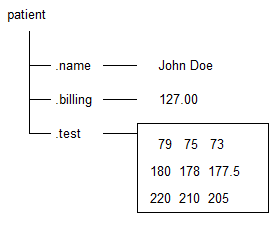

那有以下兩種造法：

clear
% method 1
patient.name = 'John Doe';
patient.billing = 127;
patient.test = [79 75 73; 180 178 177.5; 220 210 205];
patient

% method 2
% s = struct(field1,value1,...,fieldN,valueN)
patient = struct('name', 'John Doe', ...
    'billing', 127, ...
    'test', [79 75 73; 180 178 177.5; 220 210 205] ...

patient = struct with fields:
       name: 'John Doe'
    billing: 127
       test: [3×3 double]


    );
patient

% check
class(patient)
isstruct(patient)

雖然上面的寫法，都會讓你把 structure array 快速地聯想到 python dictionary，但還是要呼籲，別忘了，可以把它想成只有一個 row 的 table。因為這種想法對等等的概念擴展是有幫助的。

### Access values in Fields

要取值的話，因為從資料結構來看，就是個 python dictionary，所以就一路點下去就好：

patient.name

patient = struct with fields:
       name: 'John Doe'
    billing: 127
       test: [3×3 double]


patient.billing
patient.test
patient.test(1,3) % 一路 chain 下去

ans = 'struct'

## nonscalar structure array

就是 list of dictionary 啦，或想成 table 也可。

舉例來說，我今天想搜集病人的資料：

- 從 table 的角度來看，每個病人是一個 row，然後每個病人，都有 name, billing, test 三個欄位來記錄。其中，test 把它想成醫學影像的結果好了，是個 3x3 的 matrix。

- 從 list of dictionary 的角度來看，每個病人是一個 dictionary，裡面都有 name, billing, test 三個 key 值。如下圖：

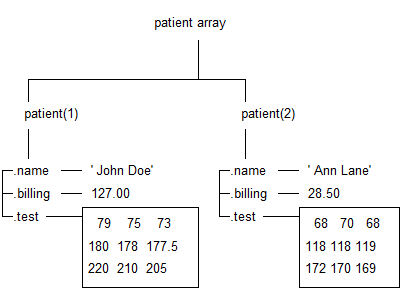

### creation

建立資料時，腦裡想的是 list of dictionary 的角度，所以這樣建：

clear

ans = logical
   1



% 第一個 dictionary /或稱為 table 的第一個 row
patient(1).name = 'John Doe';
patient(1).billing = 127;

ans = 'John Doe'

patient(1).test = [79 75 73; 180 178 177.5; 220 210 205];

ans = 127

ans =    79.0000   75.0000   73.0000
  180.0000  178.0000  177.5000
  220.0000  210.0000  205.0000


% 第二個 dictionary /或稱為 table 的第二個 row

ans = 73

patient(2).name = 'Ann Lane';
patient(2).billing = [28.50, 123];
patient(2).test = [68 70 68; 118 118 119; 172 170 169];

patient

可以看到，結果就是個 table 的樣子。這就是我說的，從直覺和視覺化的角度來理解 structure array。建議善用 matlab 的 IDE 功能，去 workspace 點 patient 這個變數。

但也別忘了資料結構的角度，可以看到，他的 dimension 會是 1x2 struct，這就是因為，從資料結構的角度來看，他是 [dictionary1, dictionary2]，所以是 1x2 的 structure array。

接著，我們要來示範這種 structure 的特性。他和 python 的 dictionary 比起來，是他會強迫補滿大家的 field：

- 每一個 structure (以此例來說，有兩個 structure)，必須有相同數量的 fields (i.e. 欄位)

- 每一個 structure 必須有相同的 filed name (欄位名稱)

- 如果有的人欄位多，有的人欄位少，他會幫你取聯集，然後缺少的地方，補 `[]` 給你 (i.e. None)

- 同樣的 filed name 下，可以接受不同的 data types

我們來實驗看看：

patient(3).name = 'Sara Sara';
% no billing info -> will replace by []
patient(3).test = [89 34 100] % 1*3 array, different from 3*3 array
patient(3).remark = 'only sara has this info';

patient

### Access values

### 取到某個節點

要取值的時候，就別忘了，用資料結構的角度去想，而不是用 table 的角度去想。

所以，從 [dictionary1, dictionary2, ...] 的角度來看，我們就要：

- 先用 list 的 index method (小括號)，取出某個 dictionary

- 再用取 key 的方式 (點)，來取出某個 key 的 value

patient(1)
patient(1).test

### 取某個 field

那因為他看起來就像個 table ，大家都有相同的欄位名稱，所以我也會想一次取一整個欄位出來

只是要注意的是，他可以接受同一個欄位，各自 data type 不同，所以，他是會分別吐值出來

patient.name

所以，你要嘛用多個 variable 去接他：

[v1, v2, V3] = patient.name

patient = 1×2 struct array with fields:
    name
    billing
    test


或是，把結果存成一個 cell array (因為，cell array 可以接受大家 data type 不同)

c = {patient.name}

## Concat

如果從 table 的角度來看，我會想新增 row

那從資料結構的角度來看，我就是要新增一個 dictionary，然後把他 concat 在 array 的最後面

% new patient
new_patient = struct('name', 'What Ever', ...

patient = 1×3 struct array with fields:
    name
    billing
    test


    'billing', 123, ...
    'test', [79 75 73; 180 178 177.5; 220 210 205], ...
    'remark', []);

patient = 1×3 struct array with fields:
    name
    billing
    test
    remark


patient = [patient, new_patient]

## 好用的 functions

這邊介紹幾個對付這種 table like 的 structure array 的好用 functions:

% 是不是 structure array
isstruct(patient)

ans = struct with fields:
       name: 'John Doe'
    billing: 127
       test: [3×3 double]
     remark: []


ans =    79.0000   75.0000   73.0000
  180.0000  178.0000  177.5000
  220.0000  210.0000  205.0000


% 列出所有欄位
fields(patient)

% 確認有沒有某個欄位

ans = 'John Doe'

ans = 'Ann Lane'

ans = 'Sara Sara'

isfield(patient, 'height')


v1 = 'John Doe'

v2 = 'Ann Lane'

V3 = 'Sara Sara'

% 刪除某個欄位
rmfield(patient, 'billing')

c = 1×3 cell array
    {'John Doe'}    {'Ann Lane'}    {'Sara Sara'}


這邊特別注意，以前在 array 要移除某欄，或某列時，都是先 subset 到那欄/那列，再指派 `[ ]` 給他，就完成刪除

但因為 structure array 他的一個欄下面，是不同的資料型態，所以不能這樣做，而是要用 `rmfield` 這個 function

## 實戰真實資料

來看例子：

load('materials_L4/ExampleStruct.mat')

資料讀進來後，去 matlab 的左邊 workspace，點開 NC 這個變數 (Normal Control group 的意思，對照組的資料)，他是一個 1x30 的 structure array，點開來長這樣：

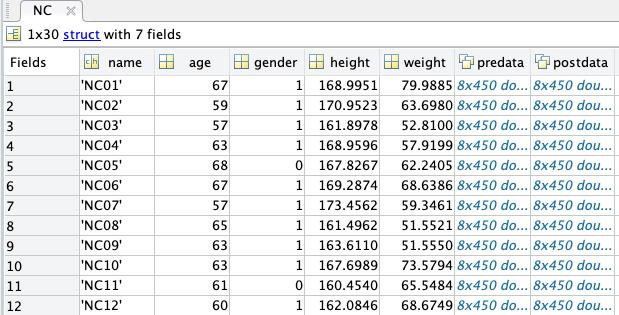

和之前學的 cell array 超像，但可以看到，現在欄位名稱都在上面了 (fileds 就是欄位名稱的意思，總共有七個欄位)

那 dimension 他寫 1x30 ，就是用資料結構的角度去想，[dictionary1, ..., dictionary 30]

那我們現在來練習取資料：

- 我想先取到第一個row，和 predata 欄位 的交接的 cell

- 裡面的某一個小區塊資料

那 matlab 其實有做小抄給你，就是

- 你點選 第一個 row 和 predata 欄位的交接 cell 後

- 框選你要 slice 的區域

- 點選 IDE 最上面的 PLOTS pannel

- 可以看到左上角就有教你如何取得資料 -> 果然和想的一樣

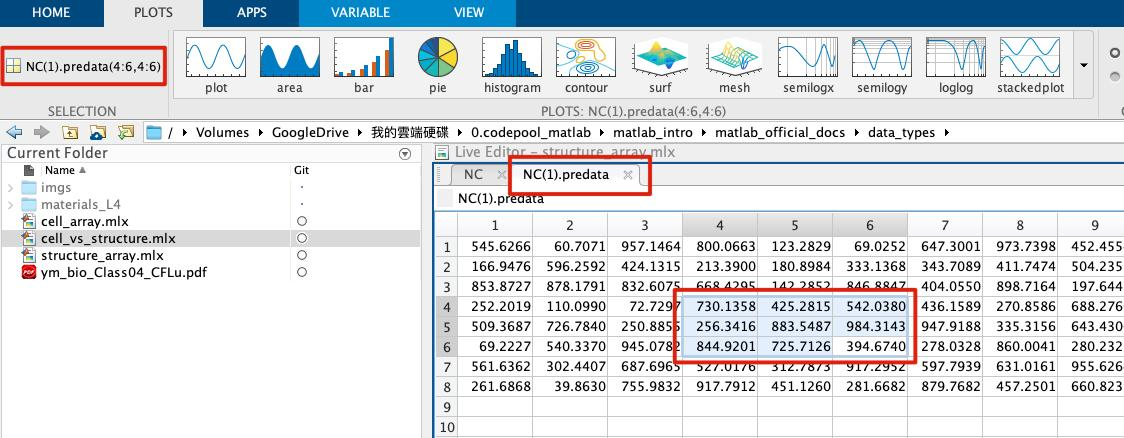

NC(1).predata(4:6, 4:6)

patient = 1×4 struct array with fields:
    name
    billing
    test
    remark


## nested array

就是你想的那個 nested dictionary

我們想作出以下的資料結構

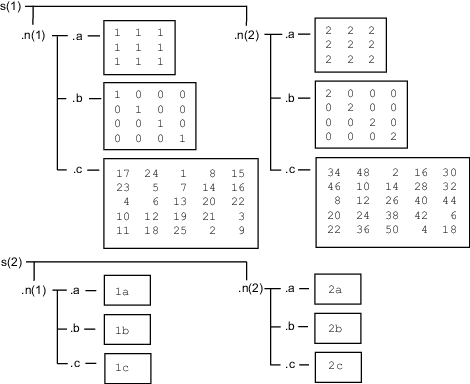

### creation

s(1).n(1).a = ones(3);

ans = logical
   1


s(1).n(1).b = eye(4);
s(1).n(1).c = magic(5);
s(1).n(2).a = 2*ones(3);

ans = 4×1 cell array
    {'name'   }
    {'billing'}
    {'test'   }
    {'remark' }


s(1).n(2).b = 2*eye(4);
s(1).n(2).c = 2*magic(5);


ans = logical
   0


s(2).n(1).a = '1a';
s(2).n(2).a = '2a';
s(2).n(1).b = '1b';

ans = 1×4 struct array with fields:
    name
    test
    remark


s(2).n(2).b = '2b';
s(2).n(1).c = '1c';
s(2).n(2).c = '2c';

s

### Access

我想取出 s1 下的 n2 下的 b 的 左上角 2x2 矩陣：

s(1).n(2).b(1:2,1:2)

## Concatenate Structures

假設有兩個 structue

struct1.a = 'first';

ans =   730.1358  425.2815  542.0380
  256.3416  883.5487  984.3143
  844.9201  725.7126  394.6740


struct1.b = [1,2,3];

struct2.a = 'second';
struct2.b = rand(5);

struct1, struct2

那，就像我們用 `[ ]` 來合併一樣： [obj1, obj2] 會做出 1x2 array; [obj1 ; obj2] 會做出 2x1 array，現在就把 obj1 換成 struct1 而已

combined = [struct1, struct2]

要取裡面的 element，也都和之前一樣

combined(1).a

那如果，我有另一個 sturcture，如下：

new(1,1).a = 1;
new(1,1).b = 10;
new(1,2).a = 2;
new(1,2).b = 20;
new(2,1).a = 3;
new(2,1).b = 30;
new(2,2).a = 4;
new(2,2).b = 40;

new

那因為，new 的 field 是 a, b，所以，可以和剛剛的 combined 合併

larger = [combined; new]

這時的，larger(1,1)，就是 combined(1,:); larger(1,2)，就是 combined(2,:)

larger(1,1)

s = 1×2 struct array with fields:
    n


larger(1,2)

ans =      2     0
     0     2


struct1 = struct with fields:
    a: 'first'
    b: [1 2 3]


struct2 = struct with fields:
    a: 'second'
    b: [5×5 double]


combined = 1×2 struct array with fields:
    a
    b


ans = 'first'

new = 2×2 struct array with fields:
    a
    b


larger = 3×2 struct array with fields:
    a
    b


ans = struct with fields:
    a: 'first'
    b: [1 2 3]


ans = struct with fields:
    a: 'second'
    b: [5×5 double]
